# Assignment 1. CT, Radon Transform

### Murong Xu

Here is your first assignment for the course which consists of 2 tasks. Some guidlines what is expected from you:

- It would be nice if you present your solutions using the Live Script form. 					

- Every figure should have a number and a title. In the text refer to figures by their number. Every plot should have titled axes. If the figure consists of several subplots, each one should have a self-explanatory title. 	

- Comments to the code are highly appreciated.

- Try to make your answers brief, usually 1-2 sectence are enough to answer the question.					

- Please, send me your solutions using the email anna.tenditnaya@tum.de until 1.12.2021 23:59. 

## Task 1								

**Q1.1**: Create a phantom for simulating XCT measurements. The phantom should contain ellipses and polygons of varying intensity (use phantom() and augment the resulting image). Show an image of your phantom. 

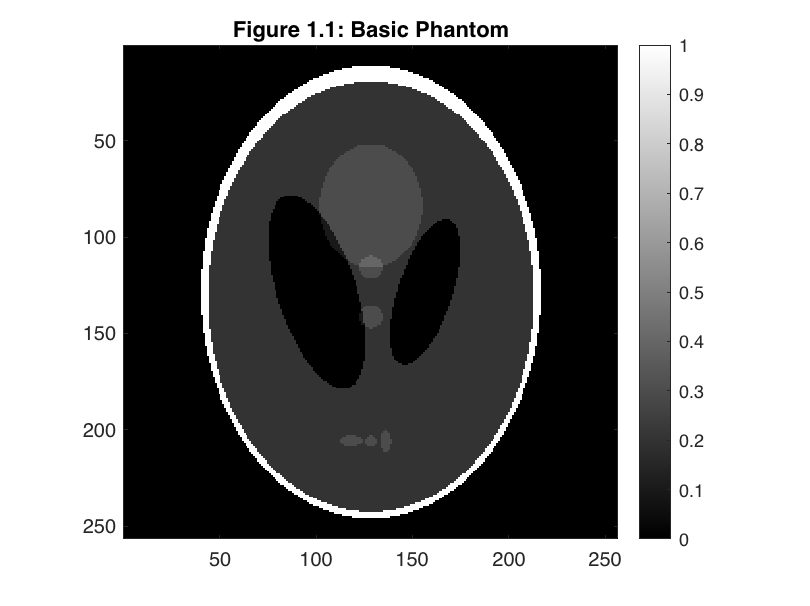

% Create a basic modified Shepp-Logan phantom with default size=256x256
% Each row of the matrix E specifies an ellipse in the image
% E has six columns, with each column containing a different parameter for the ellipses
[Phntm_basic, E_basic] = phantom('Modified Shepp-Logan');
figure(1); 
imagesc(Phntm_basic); 
axis equal tight; 
colormap gray; 
colorbar
title('Figure 1.1: Basic Phantom')

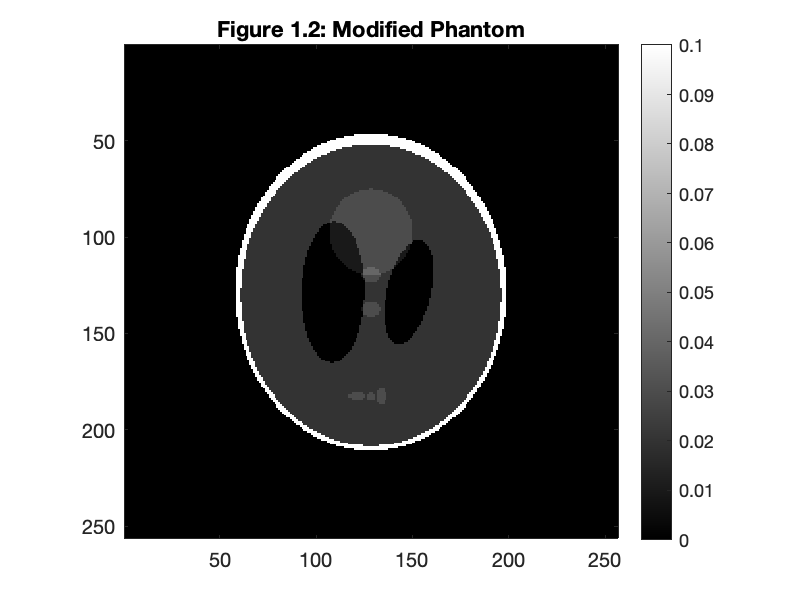


% Change the intensities and shapes of ellipses and polygons by adjusting:
% col 1 of E: additive intensity value of the ellipse
% col 2 of E: length of the horizontal semiaxis of the ellipse
% col 3 of E: length of the vertical semiaxis of the ellipse
% col 4 of E: x-coordinate of the center of the ellipse
% col 5 of E: y-coordinate of the center of the ellipse
% col 6 of E: angle (in degrees) between the horizontal semiaxis of the
% ellipse and the x-axis of the image
num_ellipses = size(E_basic, 1);
E_modified = E_basic;
E_modified(:, 1) = E_modified(:, 1) .* 0.1;
E_modified(:, 2) = E_modified(:, 2) .* 0.8;
E_modified(:, 3) = E_modified(:, 3) .* 0.7;
E_modified(:, 4) = E_modified(:, 4) .* 0.7;
E_modified(:, 5) = E_modified(:, 5) .* 0.7;
E_modified(:, 6) = E_modified(:, 6) .* randn(num_ellipses, 1);
Phntm_modified = phantom(E_modified);
figure(2); 
imagesc(Phntm_modified); 
axis equal tight; 
colormap gray; 
colorbar
title('Figure 1.2: Modified Phantom')

**Q1.2**: Compute the views (projections) for the range of angles from 0° to 179° with spacing of 1°, 5° and 10°. Show the projections at 0°, 30°, 45° and 90° (in one axes). Show the sinogram with the most angles/projections. 	

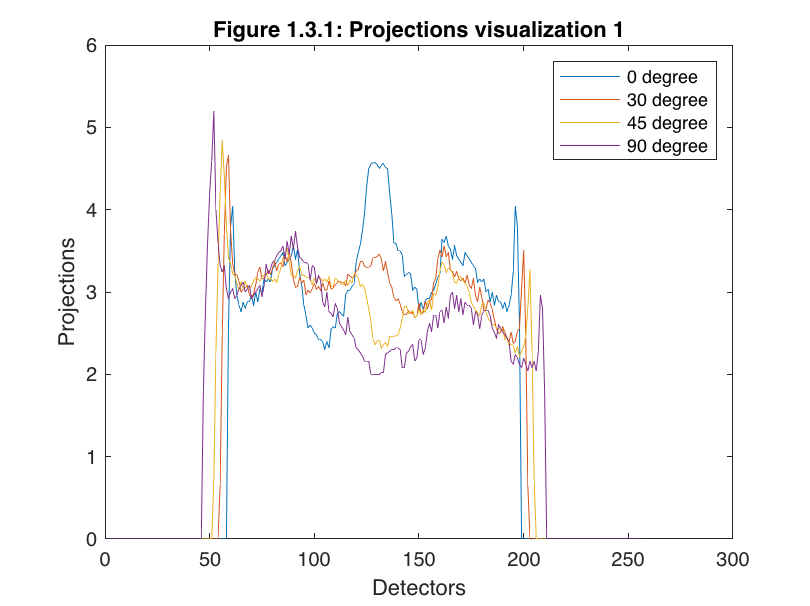

% Define the angles with different spacing values
theta_1 = 0:1:179;
theta_5 = 0:5:179;
theta_10 = 0:10:179;

% Compute the views by rotating the phantom from 0 to 179 degrees
views_stacked = zeros(length(theta_1), size(Phntm_modified, 2));
for i = 1:length(theta_1)
    Phntm_rotate = imrotate(Phntm_modified, theta_1(i), 'bilinear', 'crop'); 
    views_stacked(i,:) = sum(Phntm_rotate); 
end

% Views with spacing 1, 5, 10 degrees
views_stacked_1 = views_stacked;
views_stacked_5 = views_stacked(theta_5+1, :);
views_stacked_10 = views_stacked(theta_10+1, :);

% Show the projections at 0, 30, 45, 90 degrees
figure(3);
plot(views_stacked_1(1, :));
hold on
plot(views_stacked_1(31, :));
hold on
plot(views_stacked_1(46, :));
hold on
plot(views_stacked_1(91, :));
title('Figure 1.3.1: Projections visualization 1');
xlabel('Detectors')
ylabel('Projections')
legend('0 degree', '30 degree', '45 degree', '90 degree')
hold off

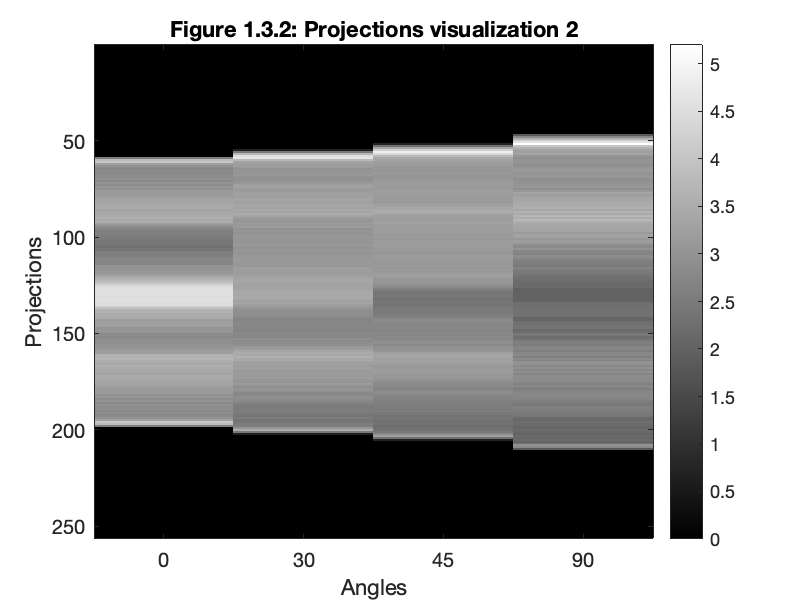


figure(4); 
imagesc(imrotate(flipud(views_stacked([1, 31, 46, 91], :)), -90));
title('Figure 1.3.2: Projections visualization 2')
xticks([1 2 3 4]) 
xticklabels({'0','30','45','90'})
xlabel('Angles')
ylabel('Projections')
colormap gray; 
colorbar

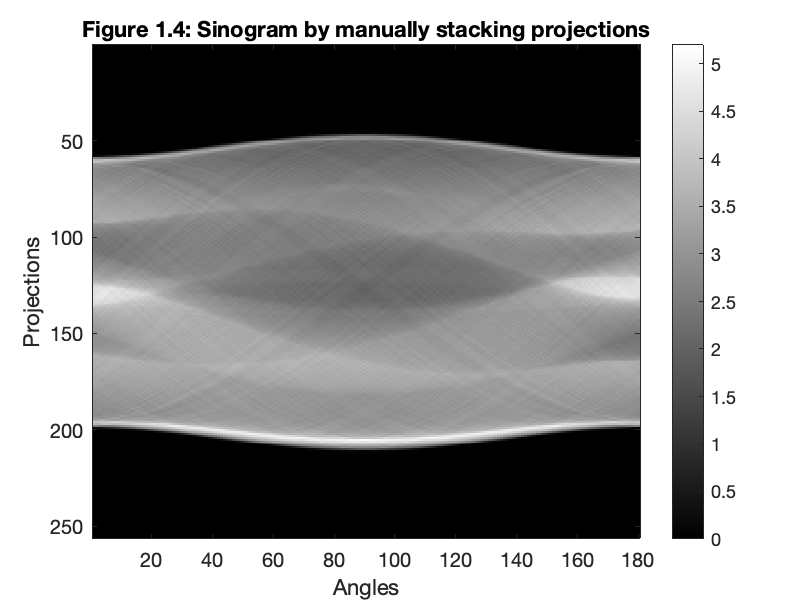


% Compute sinograms by two ways (same results)
figure(5); 
imagesc(imrotate(flipud(views_stacked), 90));
title('Figure 1.4: Sinogram by manually stacking projections')
xlabel('Angles')
ylabel('Projections')
colormap gray; 
colorbar

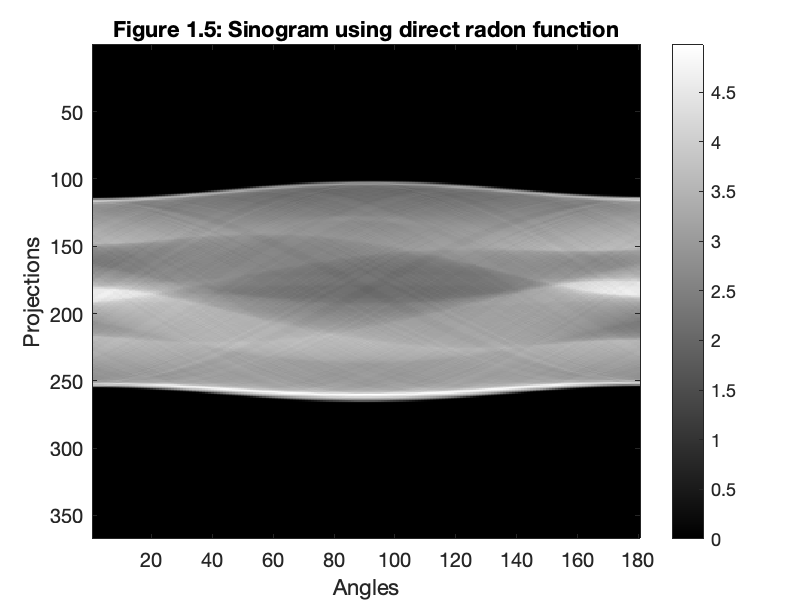


sinogram_1_radon = radon(Phntm_modified, theta_1);
figure(6); 
imagesc(sinogram_1_radon);
title('Figure 1.5: Sinogram using direct radon function')
xlabel('Angles')
ylabel('Projections')
colormap gray; 
colorbar

*Interpretation: *

*The two sinograms implemented by two different ways (Figure 1.4: manually stacking the views together, Figure 1.5: direct radon function) show the same result. The only difference is that the views are not padded in Figure 1.4. *

**Q1.3**: Implement the backprojection algorithm (i.e. inverse radon transform) according to the steps from the **Interpretation of the filtering **section from the Tutorial Live Script. You are not allowed to use iradon(). 

% See the function backprojection

**Q1.4**: Reconstruct the phantom data with the specified angular spacings using your backprojection algorithm without filtering. Show the obtained reconstructions. 

BP_unfiltered = backprojection(sinogram_1_radon, theta_1, 'none');

disp('Figure 1.6: Backprojection without filtering')
figure(7);
subplot(1,2,1);
imagesc(Phntm_modified);

Figure 1.6: Backprojection without filtering


axis equal tight;
colormap gray;
title('1.6.1: Original phantom'); 
subplot(1,2,2);
imagesc(BP_unfiltered);
axis equal tight;
colormap gray;
title('1.6.2: Unfiltered BP'); 

**Q1.5**: Incorporate filtering in your backprojection. Implement 3 filters (ramp, cosine and hamming) and test their influence on the reconstruction using your phantom data (pick a single angle spacing). Show the reconstruction results.

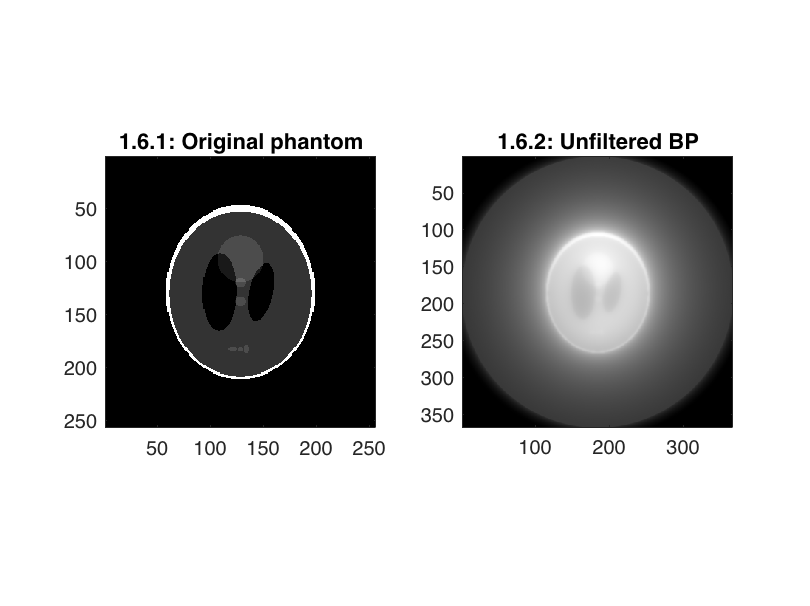

BP_filtered_ramp = backprojection(sinogram_1_radon, theta_1, 'ramp');
BP_filtered_hamming = backprojection(sinogram_1_radon, theta_1, 'hamming_window');
BP_filtered_cosine = backprojection(sinogram_1_radon, theta_1, 'cosine_window');


disp('Figure 1.7: Influence of filtering')
figure(8); 
subplot(2,2,1); imagesc(real(BP_unfiltered)); axis equal tight; colormap gray;
title('1.7.1: Unfiltered BP')
subplot(2,2,2); imagesc(real(BP_filtered_ramp)); axis equal tight; colormap gray;
title('1.7.2: Filtered BP,', 'Ramp filter')

Figure 1.7: Influence of filtering


subplot(2,2,3); imagesc(real(BP_filtered_hamming)); axis equal tight; colormap gray;
title('1.7.3: Filtered BP,', 'Hamming filter')
subplot(2,2,4); imagesc(real(BP_filtered_cosine)); axis equal tight; colormap gray;
title('1.7.4: Filtered BP,', 'Cosine filter')

**Q1.6**: Reconstruct the provided datasets with your backprojection algorithm without filtering and with each of the implemented filters respectively. Show the reconstructed images. 

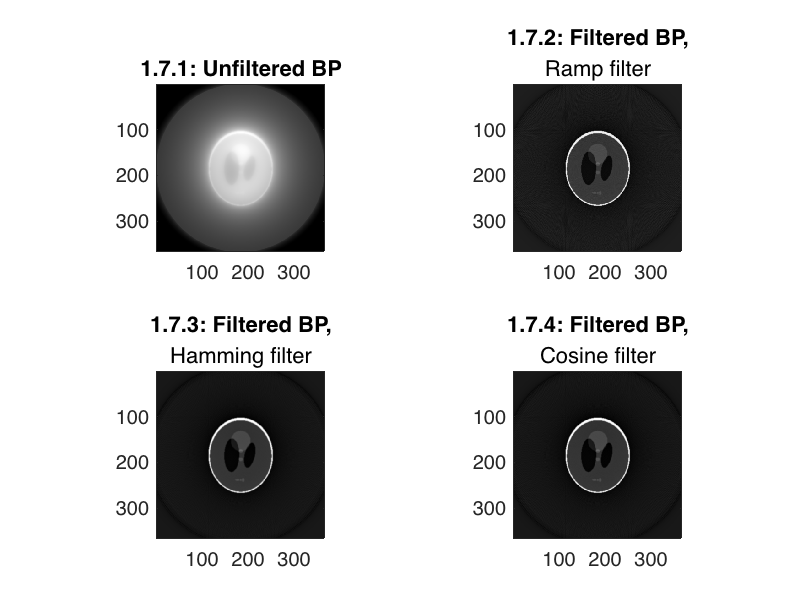

% Load dataset
dataset = load('Data.mat');
sinogram0 = dataset.sinogram0;
theta0 = dataset.theta0;
sinogram1 = dataset.sinogram1;

theta1 = dataset.theta1;

% Reconstruct the first sinogram
BP_dataset0_unfiltered = backprojection(sinogram0, theta0, 'none');
BP_dataset0_filtered_ramp = backprojection(sinogram0, theta0, 'ramp');
BP_dataset0_filtered_hamming = backprojection(sinogram0, theta0, 'hamming_window');
BP_dataset0_filtered_cosine = backprojection(sinogram0, theta0, 'cosine_window');

disp('Figure 1.8: Dataset reconstruction of sinogram 0')
figure(9); 
subplot(2,2,1); imagesc(real(BP_dataset0_unfiltered)); axis equal tight; colormap gray;
title('1.8.1: Unfiltered BP')
subplot(2,2,2); imagesc(real(BP_dataset0_filtered_ramp)); axis equal tight; colormap gray;
title('1.8.2: Filtered BP,', 'Ramp filter')
subplot(2,2,3); imagesc(real(BP_dataset0_filtered_hamming)); axis equal tight; colormap gray;
title('1.8.3: Filtered BP,', 'Hamming filter')

Figure 1.8: Dataset reconstruction of sinogram 0


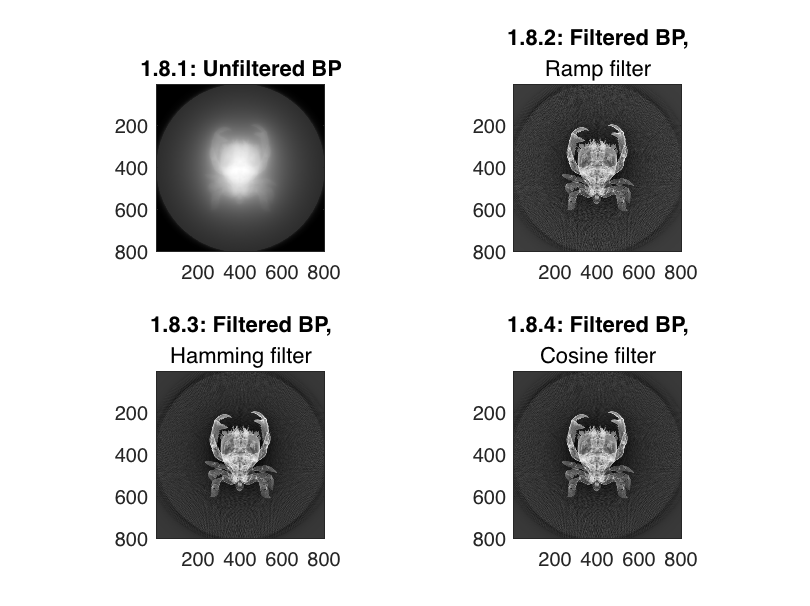

subplot(2,2,4); imagesc(real(BP_dataset0_filtered_cosine)); axis equal tight; colormap gray;
title('1.8.4: Filtered BP,', 'Cosine filter')

% Reconstruct the second sinogram
BP_dataset1_unfiltered = backprojection(sinogram1, theta1, 'none');
BP_dataset1_filtered_ramp = backprojection(sinogram1, theta1, 'ramp');
BP_dataset1_filtered_hamming = backprojection(sinogram1, theta1, 'hamming_window');
BP_dataset1_filtered_cosine = backprojection(sinogram1, theta1, 'cosine_window');


disp('Figure 1.9: Dataset reconstruction of sinogram 1')
figure(10); 
subplot(2,2,1); imagesc(real(BP_dataset1_unfiltered)); axis equal tight; colormap gray;
title('1.9.1: Unfiltered BP')
subplot(2,2,2); imagesc(real(BP_dataset1_filtered_ramp)); axis equal tight; colormap gray;
title('1.9.2: Filtered BP,', 'Ramp filter')
subplot(2,2,3); imagesc(real(BP_dataset1_filtered_hamming)); axis equal tight; colormap gray;
title('1.9.3: Filtered BP,', 'Hamming filter')

Figure 1.9: Dataset reconstruction of sinogram 1


subplot(2,2,4); imagesc(real(BP_dataset1_filtered_cosine)); axis equal tight; colormap gray;
title('1.9.4: Filtered BP,', 'Cosine filter')

**Q1.7**: Shortly interpret your results:								

- What is the effect of different angular spacings on the reconstruction? 

            *When the angular spacing is smaller -> we will obtain more projections -> know more information about the image, less artefacts -> better reconstruction quality.*

- How do the different filters change the reconstruction results? 

            *The filtering compensates for the reduction of information density at higher frequencies, s.t. it can influence the sharpness, noisy level of the reconstruction image. *

*             BP without filtering: reconstruction is blurry.*

*             BP with ramp: reconsrtuction is sharp but noisy.*

*             BP with hamming/cosine window: get a trade-off, sharp while not so noisy. *

- Which filter performs best? Why? Under which circumstances? 

             *Hamming filter. Because according to the reconstruction result, it has the minimal amount of noise in the background. While cosine filter also achieved a reasonable good result. *

*            * When the data does not contain noise: ramp filter is enough to compensate the information densities.*

*            * When the data contains noise (usually): ramp filter will amplify the noise at high frequencies. Should better use Hamming filter or Cosine filter.*

Useful commands: *radon(), fft(), fftshift(), ifft(), ifftshift(), hamming(), cos(), repmat(), imrotate(), linspace().*

## Task 2

Assume the 2x2 discretization of the spatial distribution of absorption coefficient shown in Fig. 1 and 2 point detectors with spacing L. 

**Q2.1**: Design a model matrix 𝐀 that relates X-ray measurements $\mathrm{p}={\left(P_1 ,P_2 ,P_3 ,P_4 ,P_5 ,P_6 \right)}^T$ at 3 shown angles to the (unknown) absorption $\mu ={\left(\mu_1 ,\mu_2 ,\mu_3 ,\mu_4 \right)}^T$ as in: $A\mu =p$. Show $A$. 

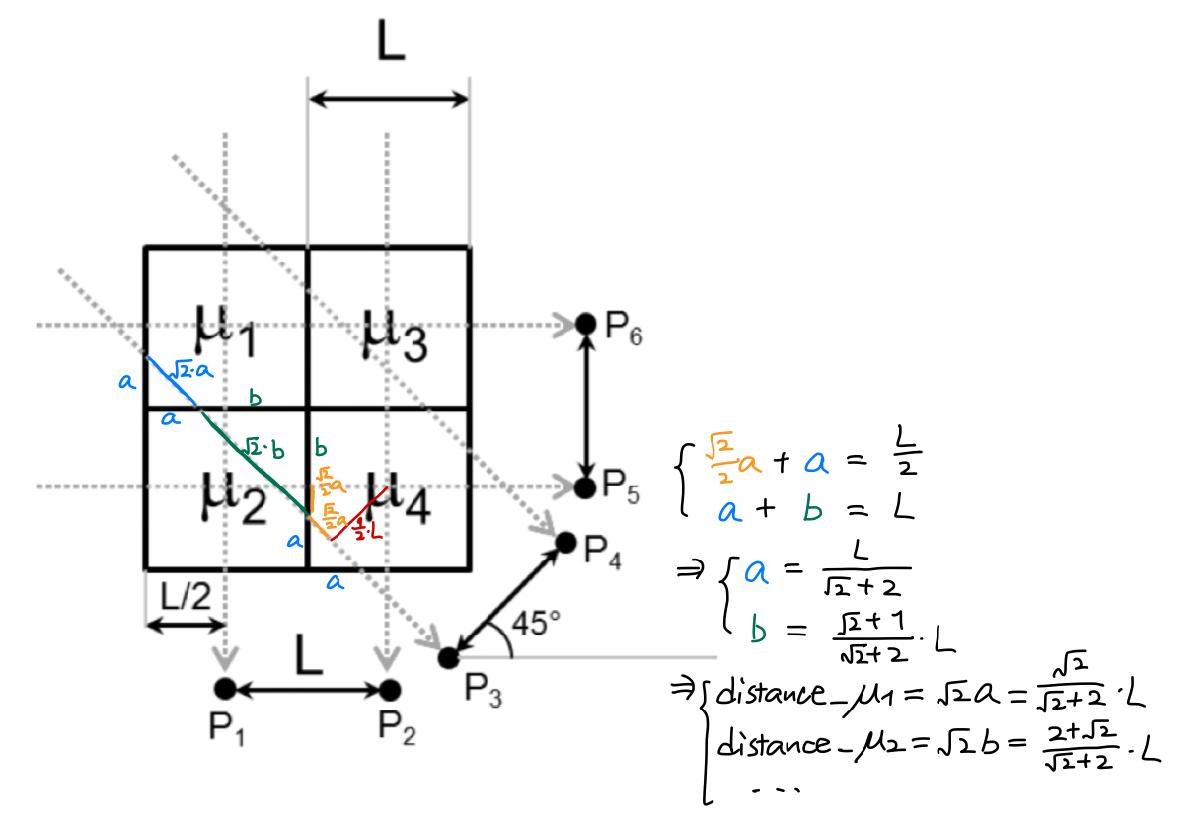

So that the matrix A is:

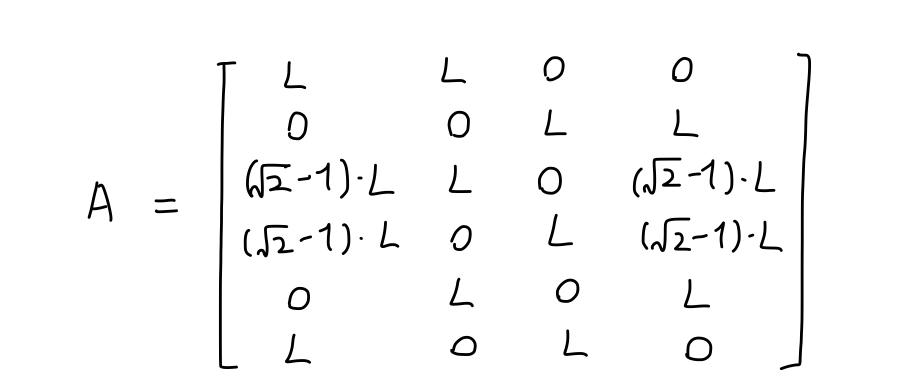

**Q2.2**: Assume a specific distribution (values) of $\mu_{\textrm{test}}$ and a specific value of L. Simulate the corresponding measurements $p_{\textrm{test}}$ for this distribution using the model matrix $A$. Show $p_{\textrm{test}}$. 

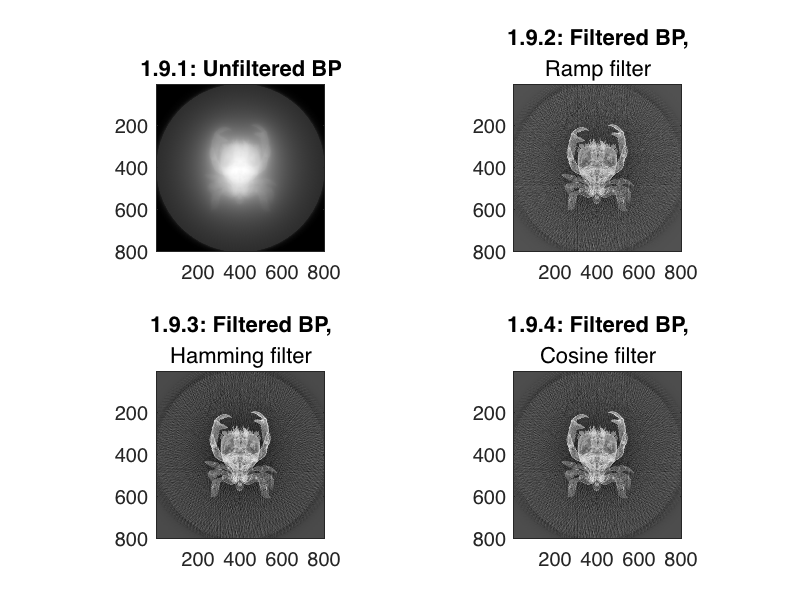

% Specify the parameters
factor = sqrt(2) - 1;
L_test = 2;
mu_test = [20, 30, 40, 50].';

A_test = [L_test, L_test, 0, 0;
0, 0, L_test, L_test;

factor*L_test, L_test, 0, factor*L_test;
factor*L_test, 0, L_test, factor*L_test;
0, L_test, 0, L_test;
L_test, 0, L_test, 0];

p_test = A_test * mu_test;
display(p_test)

**Q2.3**: Using the simulated measurements $p_{\textrm{test}}$, reconstruct absorption $\mu_{\textrm{rec}}$, i.e. solve $A\mu_{\textrm{rec}} =p_{\textrm{test}} \ldotp$Show both the assumed ($\mu_{\textrm{test}}$) and the reconstructed ($\mu_{\textrm{rec}}$) absorption distributions.

mu_rec = lsqr(A_test, p_test);
disp('Test mu:')
display(mu_test)
disp('Reconstructed mu:')
display(mu_rec)
disp('Reconstruction error:')
display(mu_test - mu_rec)

p_test =   100.0000
  180.0000
  117.9899
  137.9899
  160.0000
  120.0000


lsqr converged at iteration 4 to a solution with relative residual 2.3e-13.


Test mu:


mu_test =     20
    30
    40
    50


Reconstructed mu:


mu_rec =    20.0000
   30.0000
   40.0000
   50.0000


Reconstruction error:


   1.0e-11 *

    0.7962
    0.8569
    0.8484
    0.8022



**Q2.4**: Shortly interpret your result: 															

- Does the reconstruction $\mu_{\textrm{rec}}$ correspond to the assumed distribution $\mu_{\textrm{test}}$ of the absorption coefficient? 

            *Yes, the reconstruction error is considerably small. *

- Did you use *inv()* for inverting the model? Why? 

            *No, because inv() is used to compute the inverse of a square matrix. A is not square. *